#### Gambler brings $100 as initial budget. Leaves if he busts ($0) or if he makes double the intial budget ($200)

tic;
addpath ../dablab_files/dablab_repo/
latex_interpreter

budget = 100;
bet = 1;

withdraw = 20;
numTurns = (withdraw/bet)*100

numTurns = 20000

% numTurns = 1000;
B = zeros(withdraw/bet+1, withdraw/bet+1);
size(B)

ans =    201   201


p_win_b1 = 4/38

p_win_b1 = 0.1053

% p_win_b1 = 1/2;
p_win_b2 = 27/38;
% p_win_b2 = 1/2;
M = 3;

for FROMbudget = 0:bet:withdraw
    for TObudget = 0:bet:withdraw
        if FROMbudget == 0
            if TObudget == 0
                B(FROMbudget/bet+1, TObudget/bet+1) = 1;
            end
        elseif FROMbudget == withdraw
            if TObudget == withdraw
                B(FROMbudget/bet+1, TObudget/bet+1) = 1;
            end
        elseif TObudget == FROMbudget - bet
            if mod(FROMbudget, M) == 0
                B(FROMbudget/bet+1, TObudget/bet+1) = 1-p_win_b1;
            else
                B(FROMbudget/bet+1, TObudget/bet+1) = 1-p_win_b2;
            end
        elseif TObudget == FROMbudget + bet
                if mod(FROMbudget, M) == 0
                    B(FROMbudget/bet+1, TObudget/bet+1) = p_win_b1;
                else
                    B(FROMbudget/bet+1, TObudget/bet+1) = p_win_b2;
                end
        end
    end
end

B

B =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2895         0    0.7105         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


B_inf = B^numTurns

B_inf =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0 

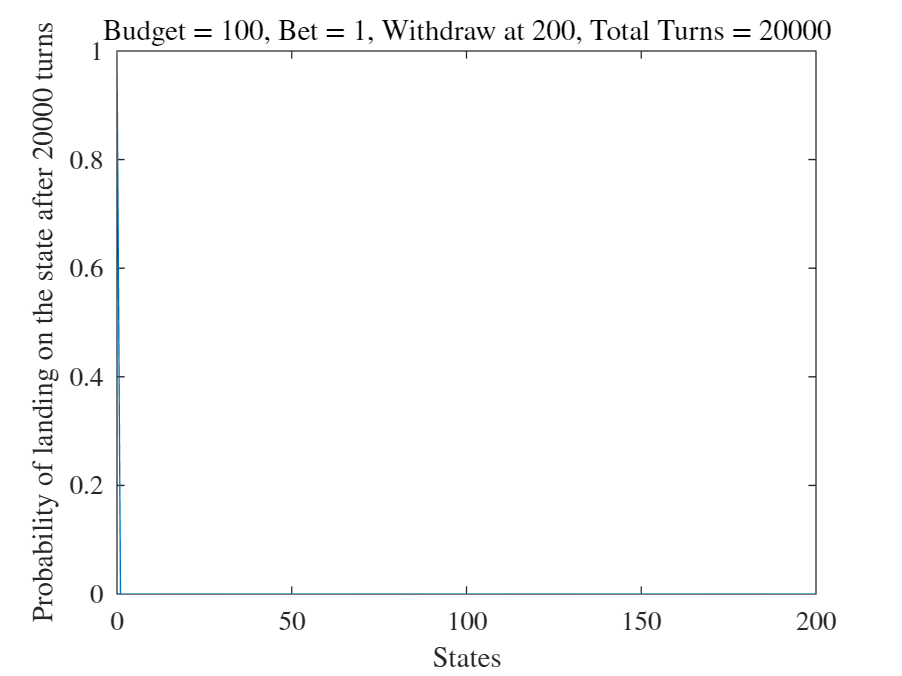

states = 0:bet:withdraw;
plot(states, B_inf(budget/bet+1, :))
title(strcat("Budget =  ", num2str(budget), ", Bet = ", num2str(bet), ...
    ", Withdraw at ", num2str(withdraw), ...
    ", Total Turns = ", num2str(numTurns)))
% xticks(states)
xlabel('States')
ylabel(strcat(['Probability of landing'  ...
    ' on the state after ', num2str(numTurns), ' turns']));

toc;

Elapsed time is 0.182049 seconds.
